# Control 7-Segment Display with 74HC595 Shift Register

This example shows how to use the MATLAB® Support Package for Arduino® Hardware to control a 1-Digit 7-Segment display with a 74HC595 8-bit serial-in-parallel-out shift register.

## Hardware Requirements

- Arduino board

- Common anode 7-segment display

- 74HC595 8-bit serial-in-parallel-out shift register

- Eight 330 ohm resistors

- Breadboard and wires

## Hardware Setup

Connect the 7-Segment display and 74HC595 shift register to Arduino hardware:

- Connect Vcc pin on 74HC595 to 5V pin on Arduino hardware.

- Connect GND and OE pins on 74HC595 to GND pin on Arduino hardware.

- Connect DS or SER pin on 74HC595 to digital pin 8 on Arduino hardware.

- Connect SHCP or SRCLK pin on 74HC595 to digital pin 10 on Arduino hardware.

- Connect STCP or RCLK pin on 74HC595 to digital pin 9 on Arduino hardware.

- Connect Q0-Q6 or QA-QG pin on 74HC595 to pin A-G on 7-segment display.

- Connect Q7 or QH pin on 74HC595 to pin DP on 7-segment display.

- Connect common anode pins (pin 3 and 8 on the diagram) on 7-segment display to 5V pin on Arduino hardware.

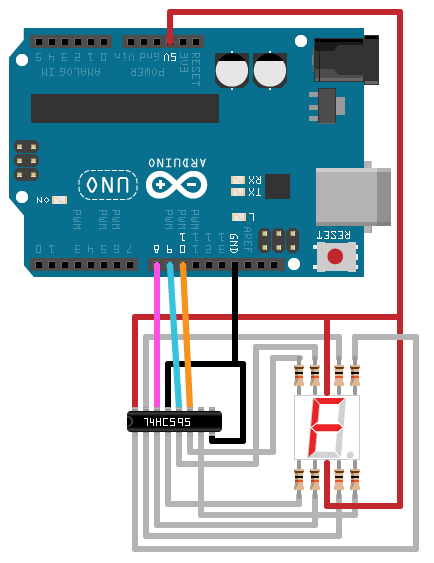

## Create Shift Register Object

Create an arduino object, and include the ShiftRegister library. 

   a = arduino('COM4','Uno','Libraries','ShiftRegister')

Create shift register object for the display module, specifying the connected data pin, clock pin, and latch pin. 

   dataPin = 'D8';
   clockPin = 'D10';
   latchPin = 'D9';
   register = shiftRegister(a,'74HC595',dataPin,clockPin,latchPin)

## Display Numbers

Each segment of the 7-segment display is controlled by a pin corresponding to the segment, including pin A-G and pin DP. Common anode 7-segment display means the segment pin needs to be low to turn it on. Here is the mapping between the segments and the pins, including shift register outputs.

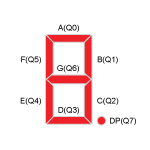

Create a table of binary character vectors for all single digit numbers.

   digitTable = {...
        '11000000', ...  % 0
        '11001111', ...  % 1
  	'10100100', ...  % 2
  	'10110000', ...  % 3
  	'10011001', ...  % 4
  	'10010010', ...  % 5
  	'10000010', ...  % 6
  	'11111000', ...  % 7
  	'10000000', ...  % 8
  	'10010000'  ...  % 9
};

To display a number on the module, write the corresponding 8-bit character vector to the shift register, which will get reflected on its outputs, therefore controlling the on and off of the segments. Here is the code to loop through the ten digits on the display,

   for iLoop = 1:10
       digit = digitTable{iLoop};
       write(register,digit);
       pause(0.5);
   end

## Clean Up

When the connection is no longer needed, clear the shift register and arduino object. 

  clear register a

*Copyright 2016 The MathWorks, Inc.*